# MiniProject-2

## Burak Aksoy

## Initialization

clear all; close all;

Define some unit vectors

zz=zeros(3,1); ex = [1;0;0]; ey = [0;1;0]; ez = [0;0;1];

Load the letter S as a curve

load S_letter_path

Show the given S curve, mark the initial point with a circle.

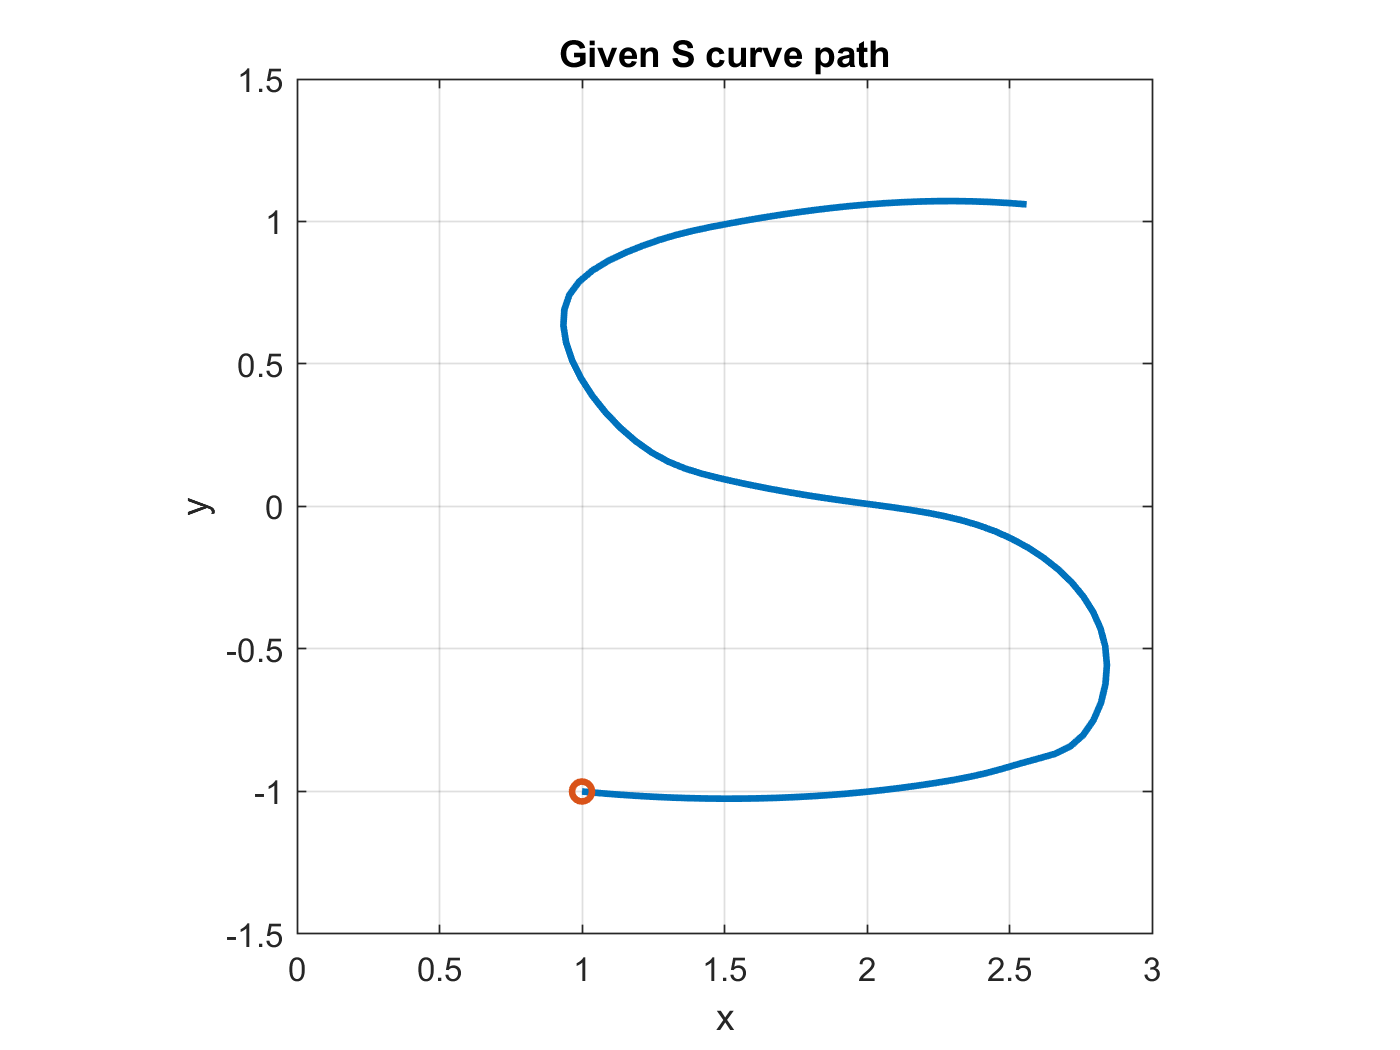

figure(1);plot(Sls(1,:),Sls(2,:),Sls(1,1),Sls(2,1),'o','linewidth',2);
xlabel('x');ylabel('y');
axis([0 3 -1.5 1.5]);axis('square');grid;
title("Given S curve path")

#### Calculate the path's (S) normal and parallel unit vectors (xT and yT respectively) at each point

(See the functions at the bottom)

[xT,yT] = setR0T(Sls);
% Add the last columns again to have the same orientation in the end
xT = [xT, xT(:,end)];
yT = [yT, yT(:,end)];

Plot path's outward normal (towards left part of the page, ie. -xT) 

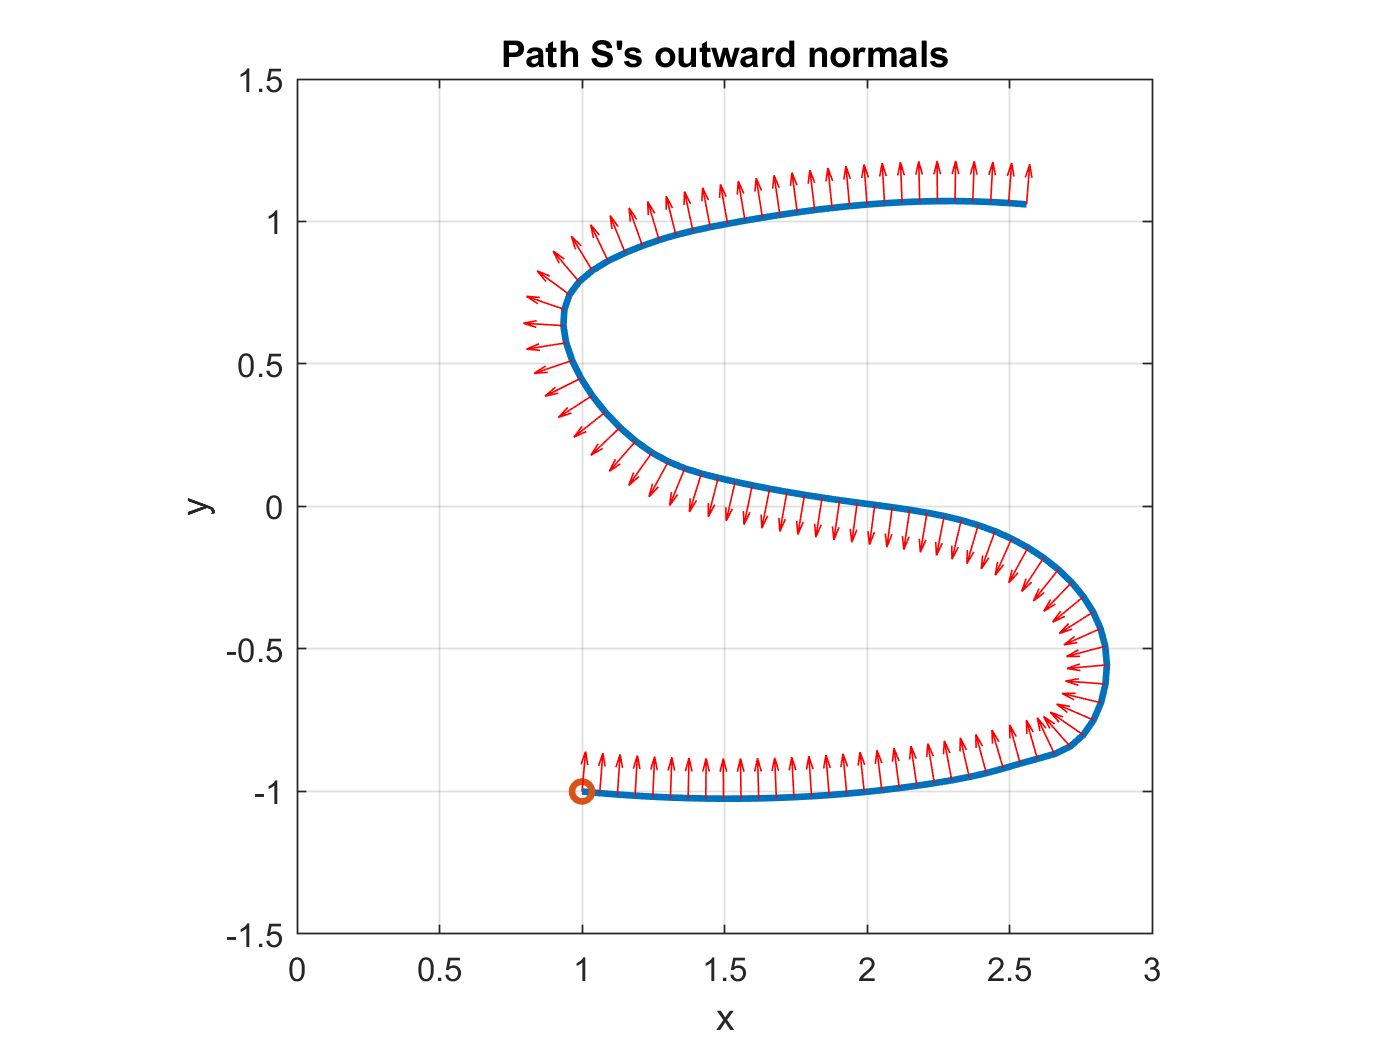

hold on;
quiver(Sls(1,:),Sls(2,:),-xT(1,:),-xT(2,:), 'r','AutoScaleFactor',0.5);
title("Path S's outward normals")

#### Generate path length array $\lambda$ corresponding to the letter S

lambda = cumsum(vecnorm(diff(Sls')'));
lambda = [0, lambda] % Add zero to the beginning so that lambda starts from 0.

lambda =          0    0.0624    0.1246    0.1869    0.2490    0.3111    0.3731    0.4351    0.4971    0.5590    0.6208    0.6827    0.7445    0.8064    0.8682    0.9300    0.9919    1.0538    1.1157    1.1777    1.2398    1.3019    1.3639    1.4257    1.4874    1.5492    1.6117    1.6743    1.7352    1.7964    1.8599    1.9260    1.9935    2.0610    2.1268    2.1908    2.2544    2.3182    2.3828    2.4481    2.5139    2.5797    2.6450    2.7090    2.7716    2.8336    2.8951    2.9566    3.0182    3.0799


## Write down the forward kinematics of the three link arm

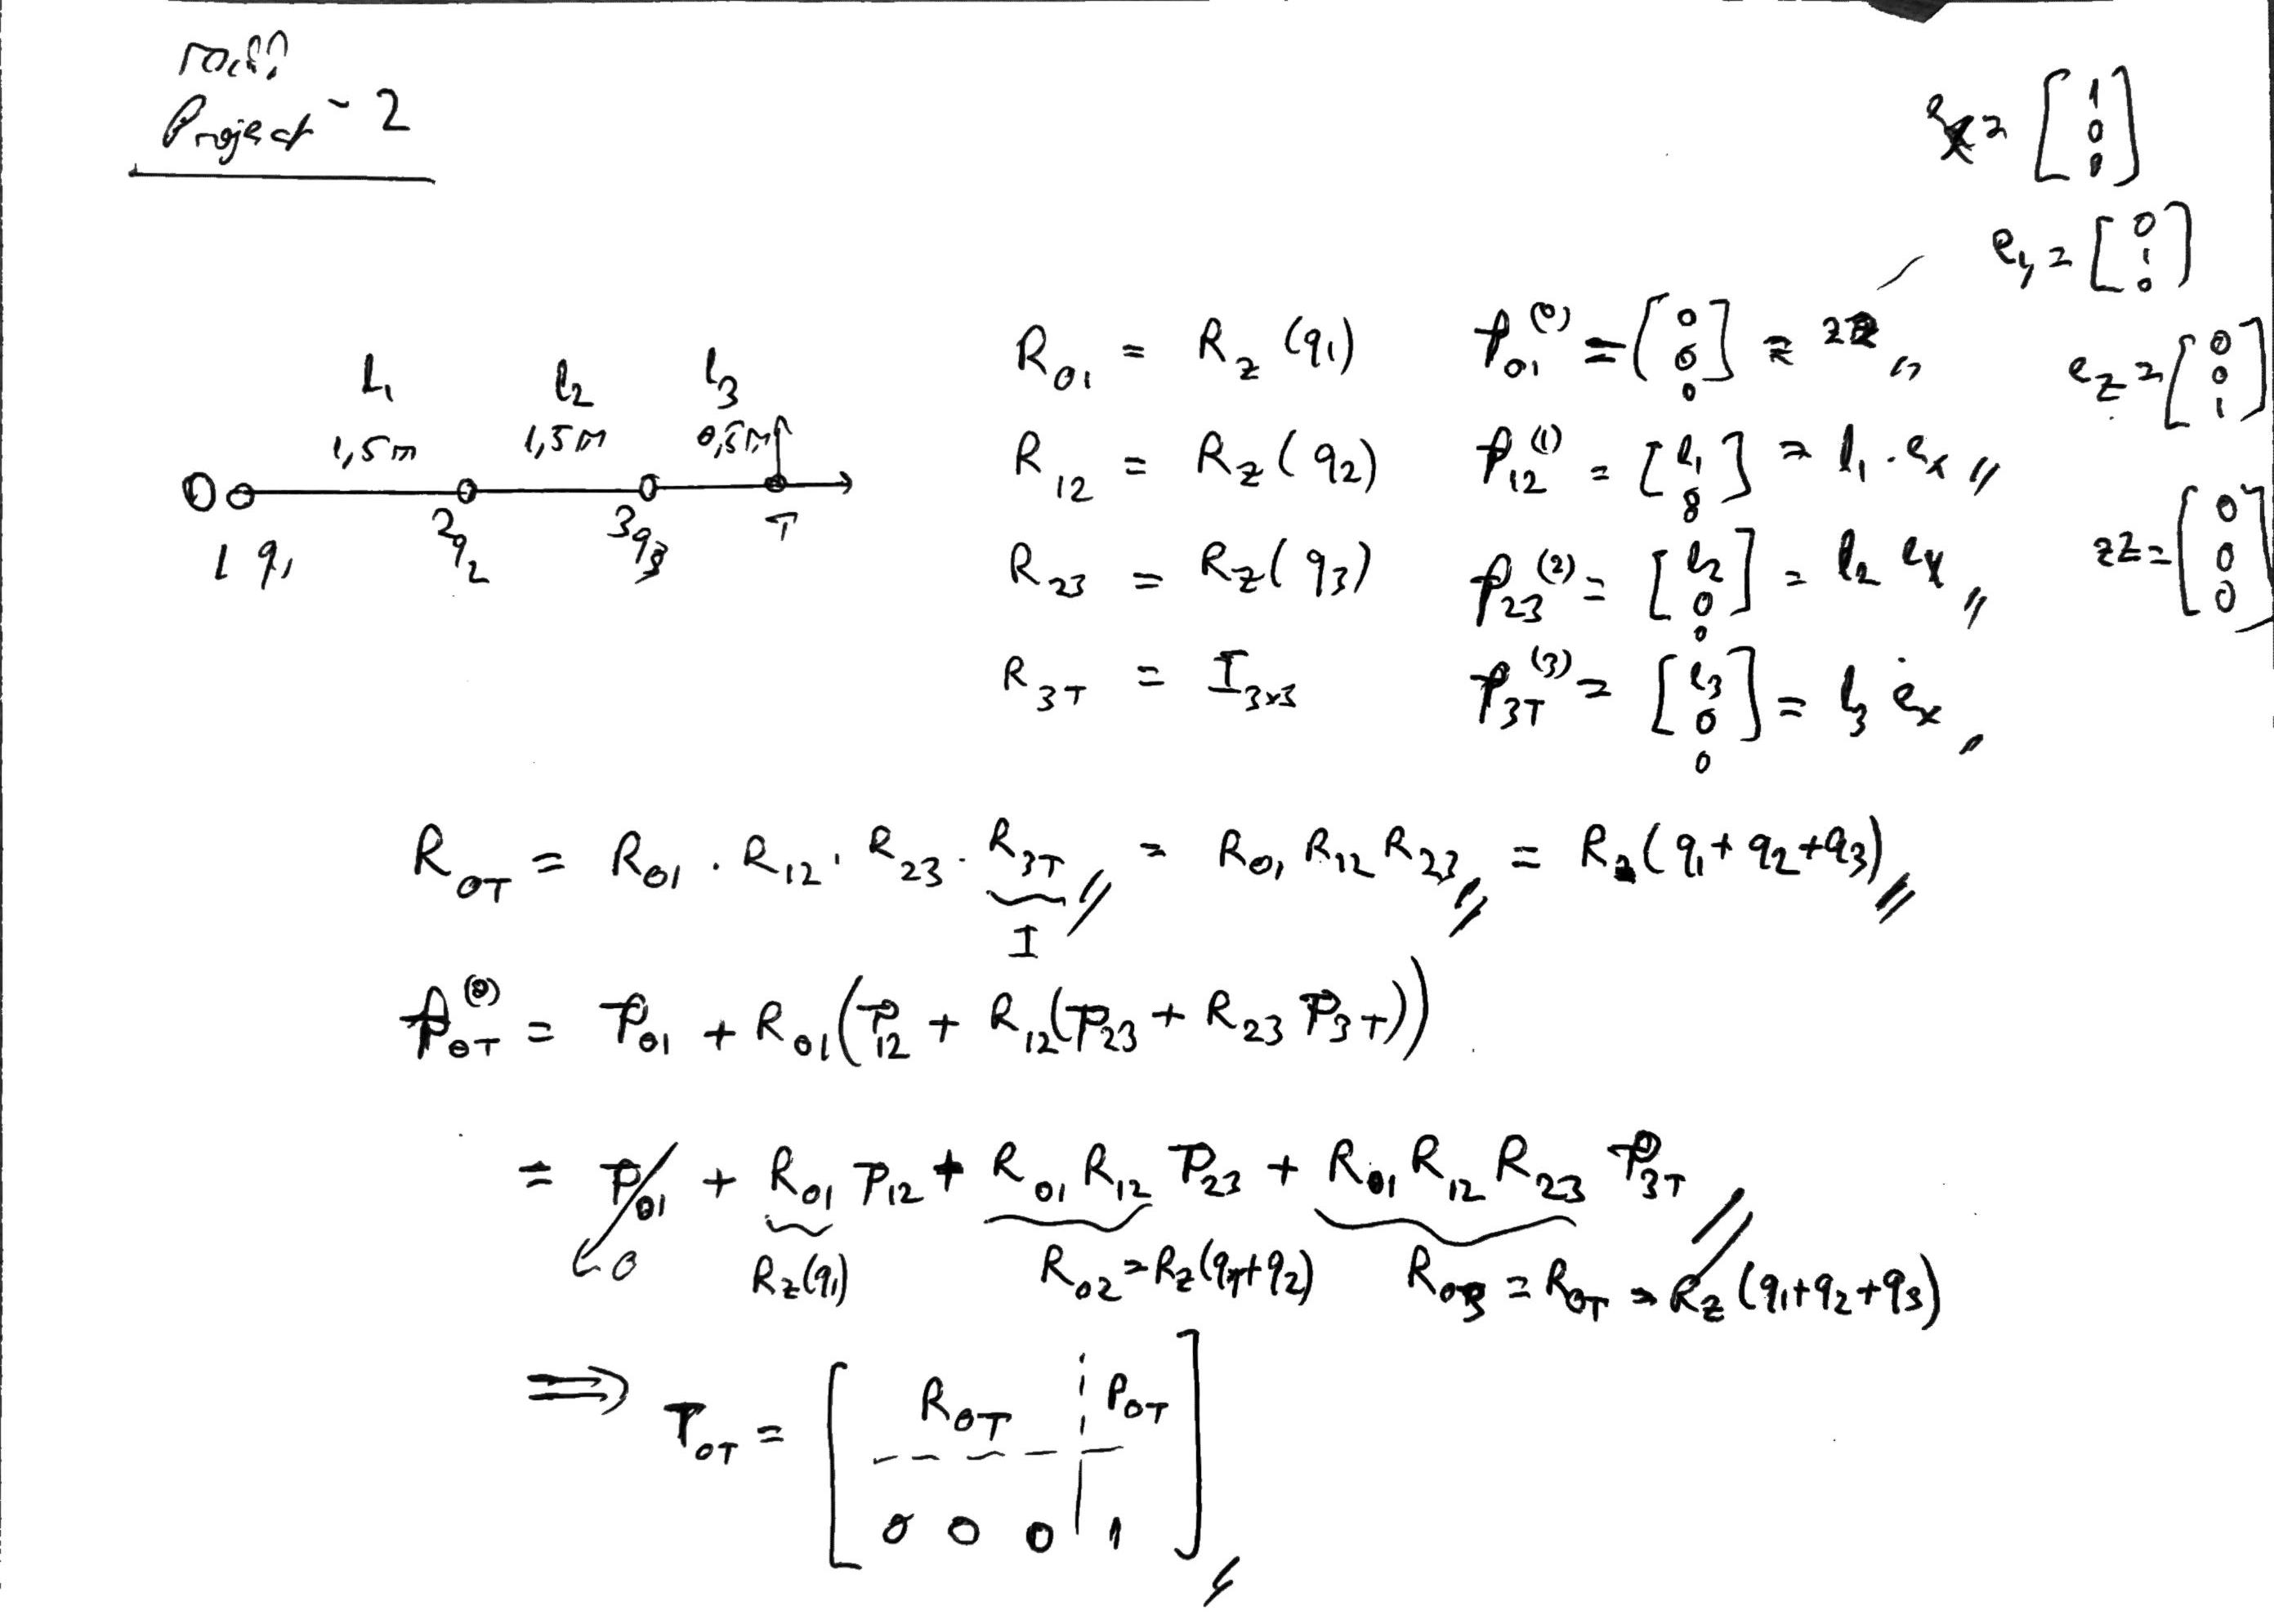

TODO: Write Jacobian

## Define robot object with its parameters

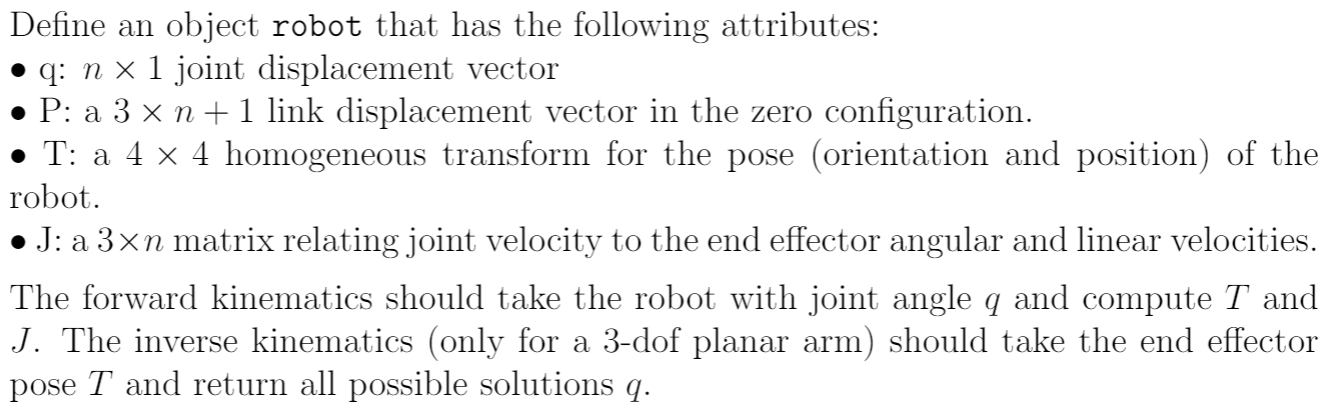

% robot parameters
l1 = 1.5; l2 = 1.5; l3 = 0.5;
robot.P = [zz l1*ex l2*ex l3*ex];
robot.H = [ez ez ez];
robot.joint_type=[0 0 0]; % revolute: 0
robot.q=[0;0;0]; % zero configuration 
radius = .01; % radius of the links (as cylinders)


Define the planar robot arm as a collision rigid body tree:

(Note that we are already given a helper function to do that from the Product of Exponential description above)

robot_rb = defineRobot(robot,radius);

Show the defined robot at it's initial configuration

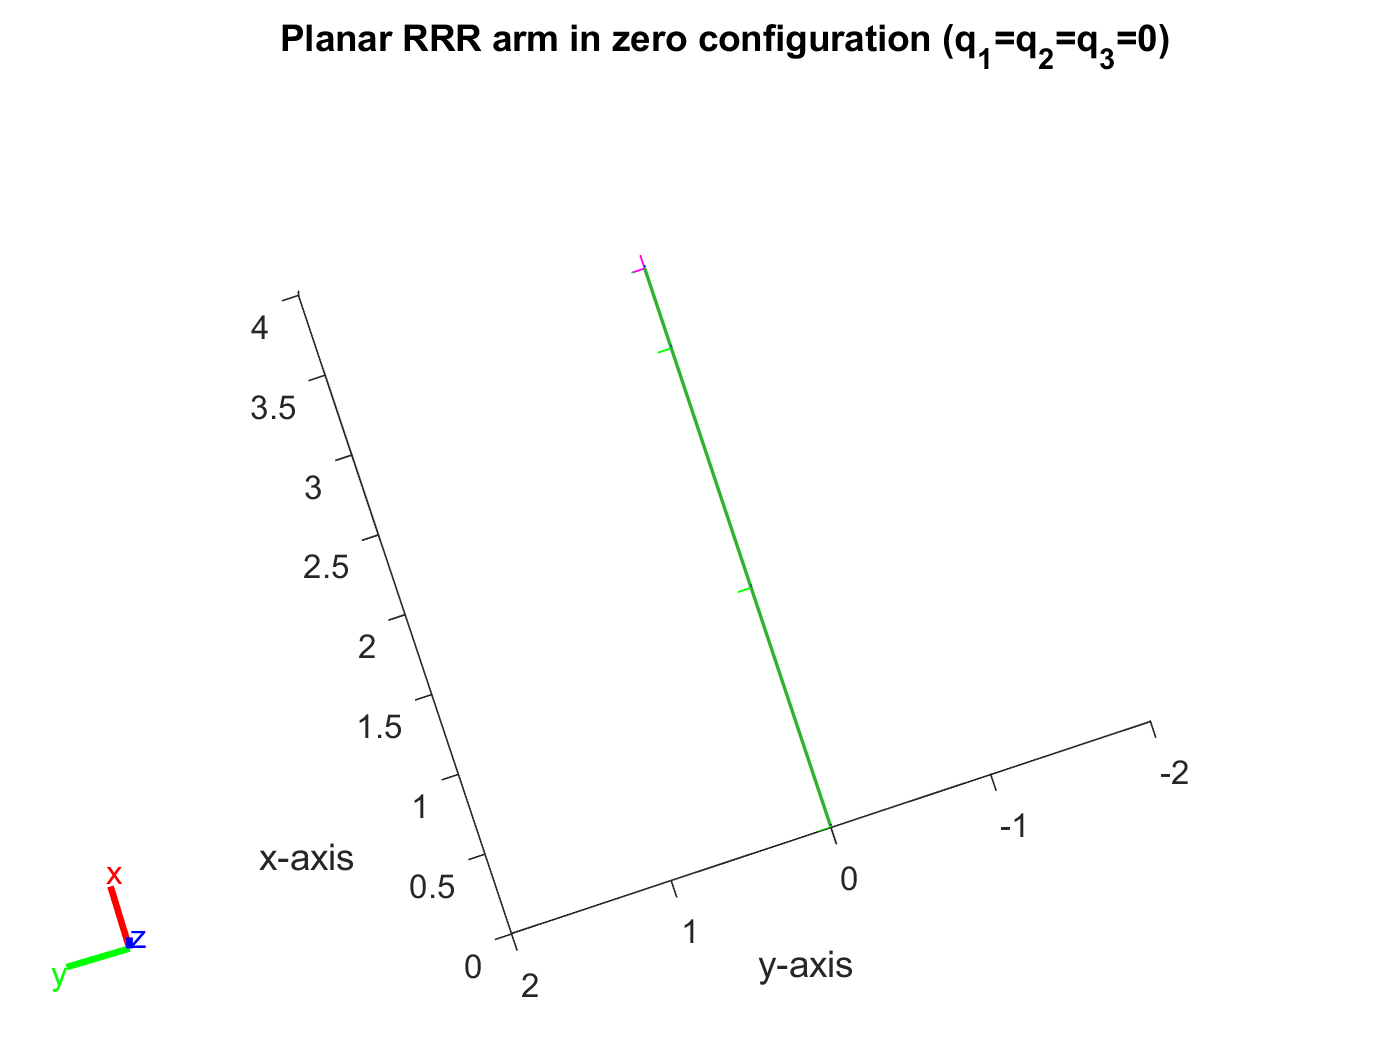

figure(2);hold on;show(robot_rb,robot.q,'Collision','on');
view(0,90);
axis([0,4,-2,2]);axis('square');
xlabel('x-axis');ylabel('y-axis');
title('Planar RRR arm in zero configuration (q_1=q_2=q_3=0)')
hold off

## Write the forward kinematics routine for the three-link arm

The forward kinematics should take the robot with joint angle q and compute T and J.

One can implement the "Recursive Form of Forward" kinematics slide at lecture 05 slides. 

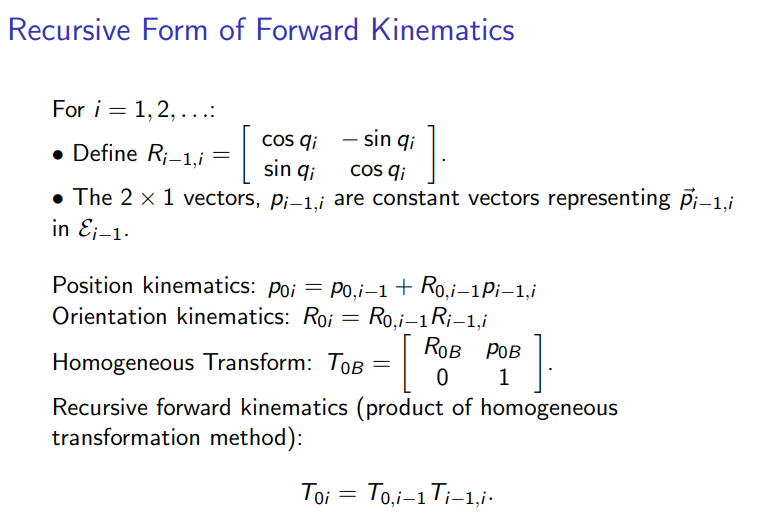

**These are implemented in **`nlinkfwdlin(robot) `**function at the bottom FUNCTIONS section.**

## Write the inverse kinematics routines for the three-link arm

The inverse kinematics (only for a 3-dof planar arm) should take the end effectorpose T and return all possible solutions q.

#### Algebraic Solution

One can implement the "Inverse Kinematics Algebraic Solution" at lecture 05 slides.

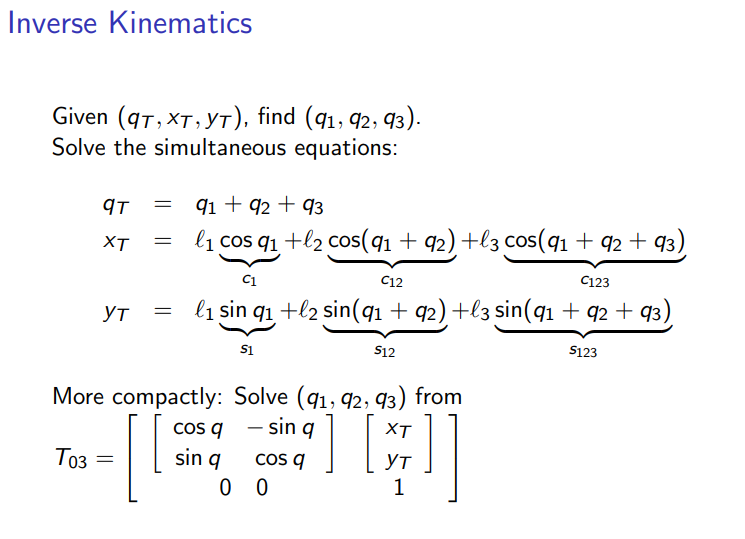

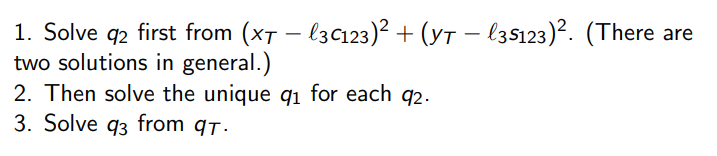

#### Geometric Solution

Another solution for inverse kinematics can be implemented from Geometric Solution with subproblems

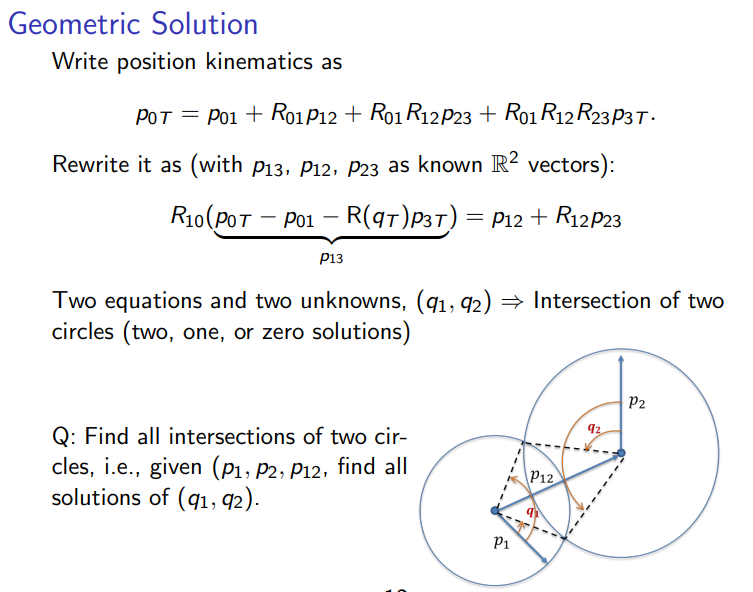

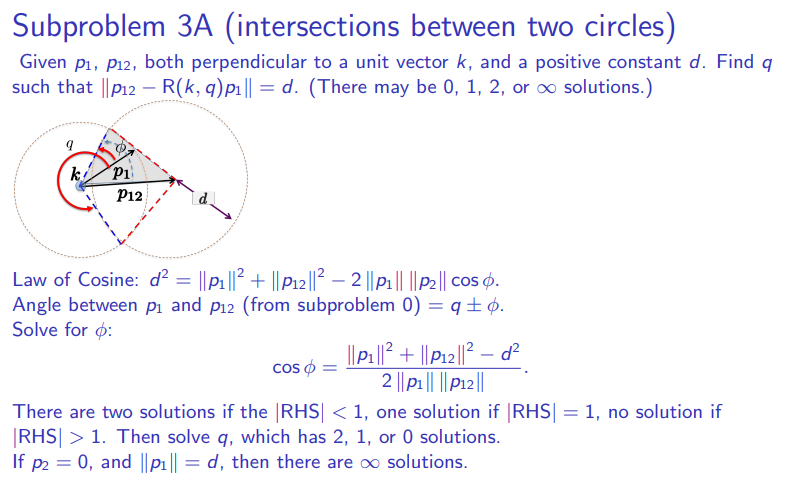

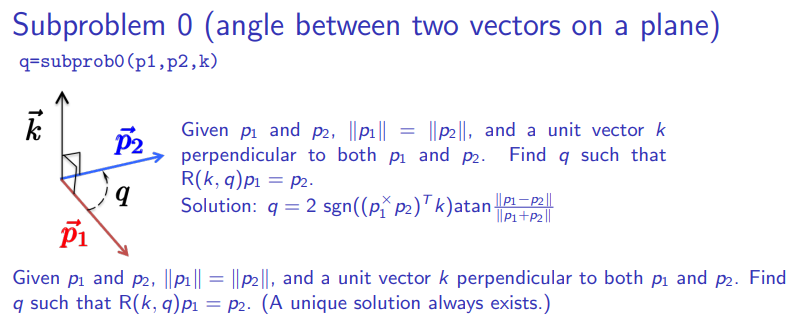

**This is implemented at **`q=threelink_invkin_geometric(robot) `**function at the FUNCTIONS section below.**

**or see **`q=threelink_invkin_geometric2(robot) `**function to use it with subproblems**

## **Verify Forward and Inverse kinematics implementations**

- **Randomly generate a joint vector q with each element  **$q_i\in[-\pi,\pi]

$

- **Use your forward kinematics code to compute T corresponding to q.**

- **Use your inverse kinematics code to compute all solutions **$q_{sol}
$**.**

- **Check that one of the **$q_{sol}
$** is your original q.**

One can use the given `threelink_kincheck.m` script to verify.

% Randomly generate a joint vector q with each element -pi to +pi
robot.q = (rand(3,1)-.5)*2*pi;

disp('random q');disp(robot.q);

random q
   -1.8363
   -1.2488
   -0.1827


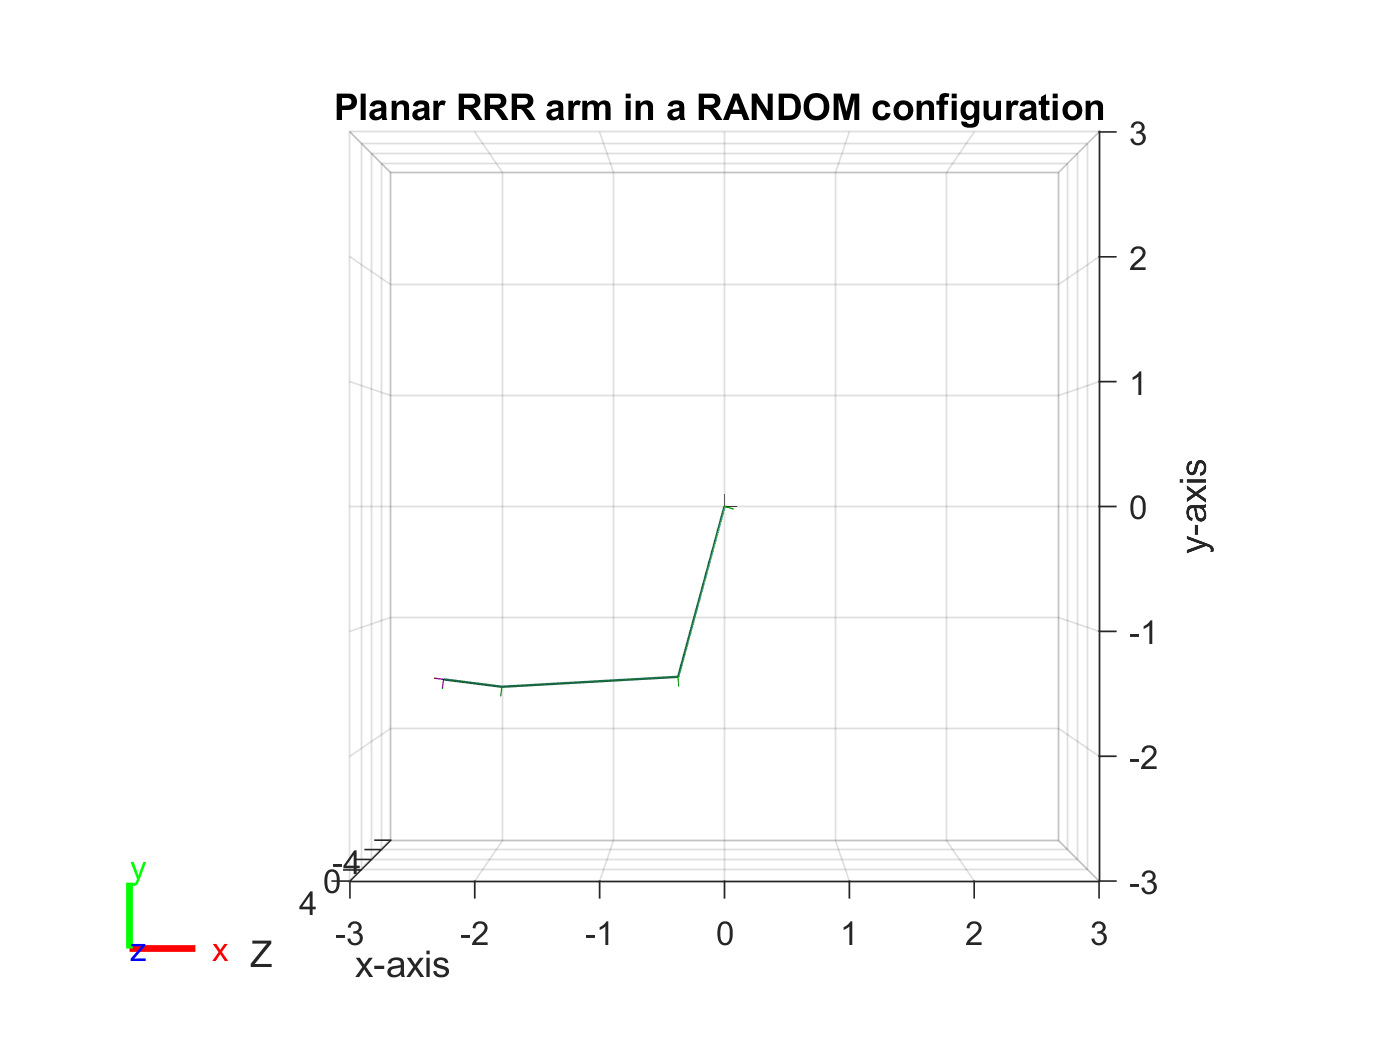


% Show the robot at the randomly generated joint angles
figure(3);show(robot_rb,robot.q,'Collision','on');
view(0,90);
axis([-3,3,-3,3]);
axis('square');
xlabel('x-axis');ylabel('y-axis');
title('Planar RRR arm in a RANDOM configuration ')

% forward kinematics
robot=nlinkfwdkin(robot);

**VERIFY geometric inverse kinematics**

% VERIFY geometric inverse kinematics (2 solutions)
qsol=threelink_invkin_geometric(robot)

qsol =    -3.0851   -1.8363
    1.2488   -1.2488
   -1.4315   -0.1827


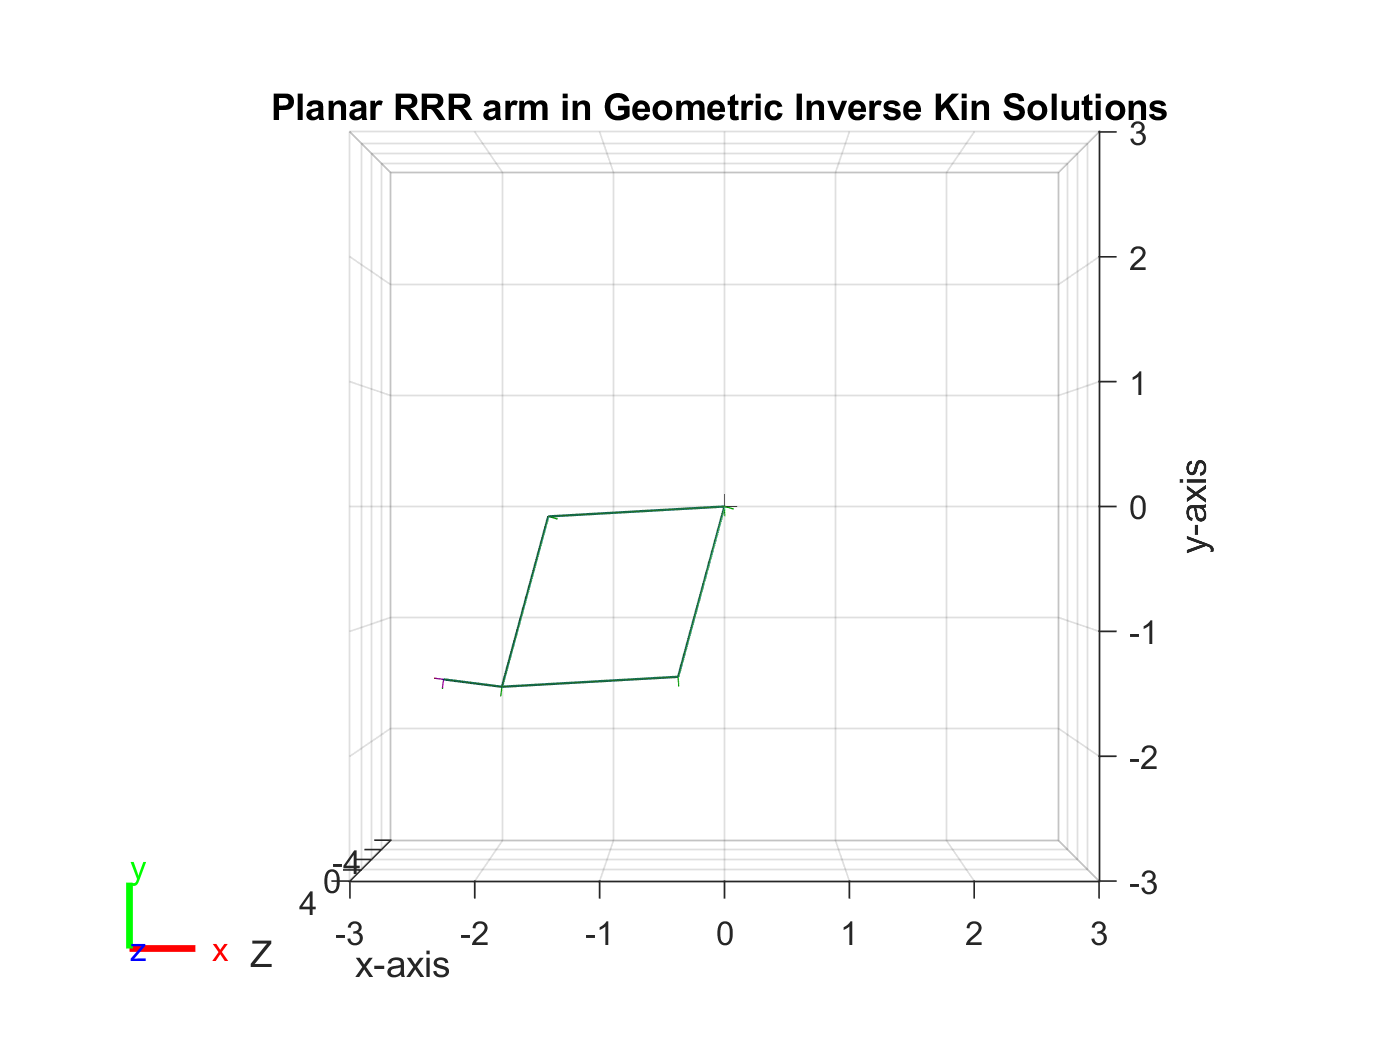


robot.q = qsol(:,1); % Solution 1

% Show the robot at the solution 1
figure(4);show(robot_rb,robot.q,'Collision','on');
view(0,90);
axis([-3,3,-3,3]);
axis('square');
xlabel('x-axis');ylabel('y-axis');
hold on; 

robot.q = qsol(:,2); % Solution 2

% Show the robot at the solution 2
show(robot_rb,robot.q,'Collision','on');
title('Planar RRR arm in Geometric Inverse Kin Solutions ');

**Note that one of the solutions is the same as the one that we have generated the robot joint angles**

## Find the desired pose for each point on the letter S path.

nl=length(Sls);
qsol1=zeros(3,nl); % To store the solution 1s
qsol2=zeros(3,nl); % To store the solution 2s
for i=1:nl
    robot.T(1:3,1:4)=[xT(:,i) yT(:,i) ez [Sls(:,i);0]];
    tstart(i)=tic;
    qsol=threelink_invkin_geometric(robot);% <<<< we implemented it
    telapsed(i)=toc(tstart(i));
    qsol1(:,i)=qsol(:,1);
    qsol2(:,i)=qsol(:,2);    
end

Plot solution 1s

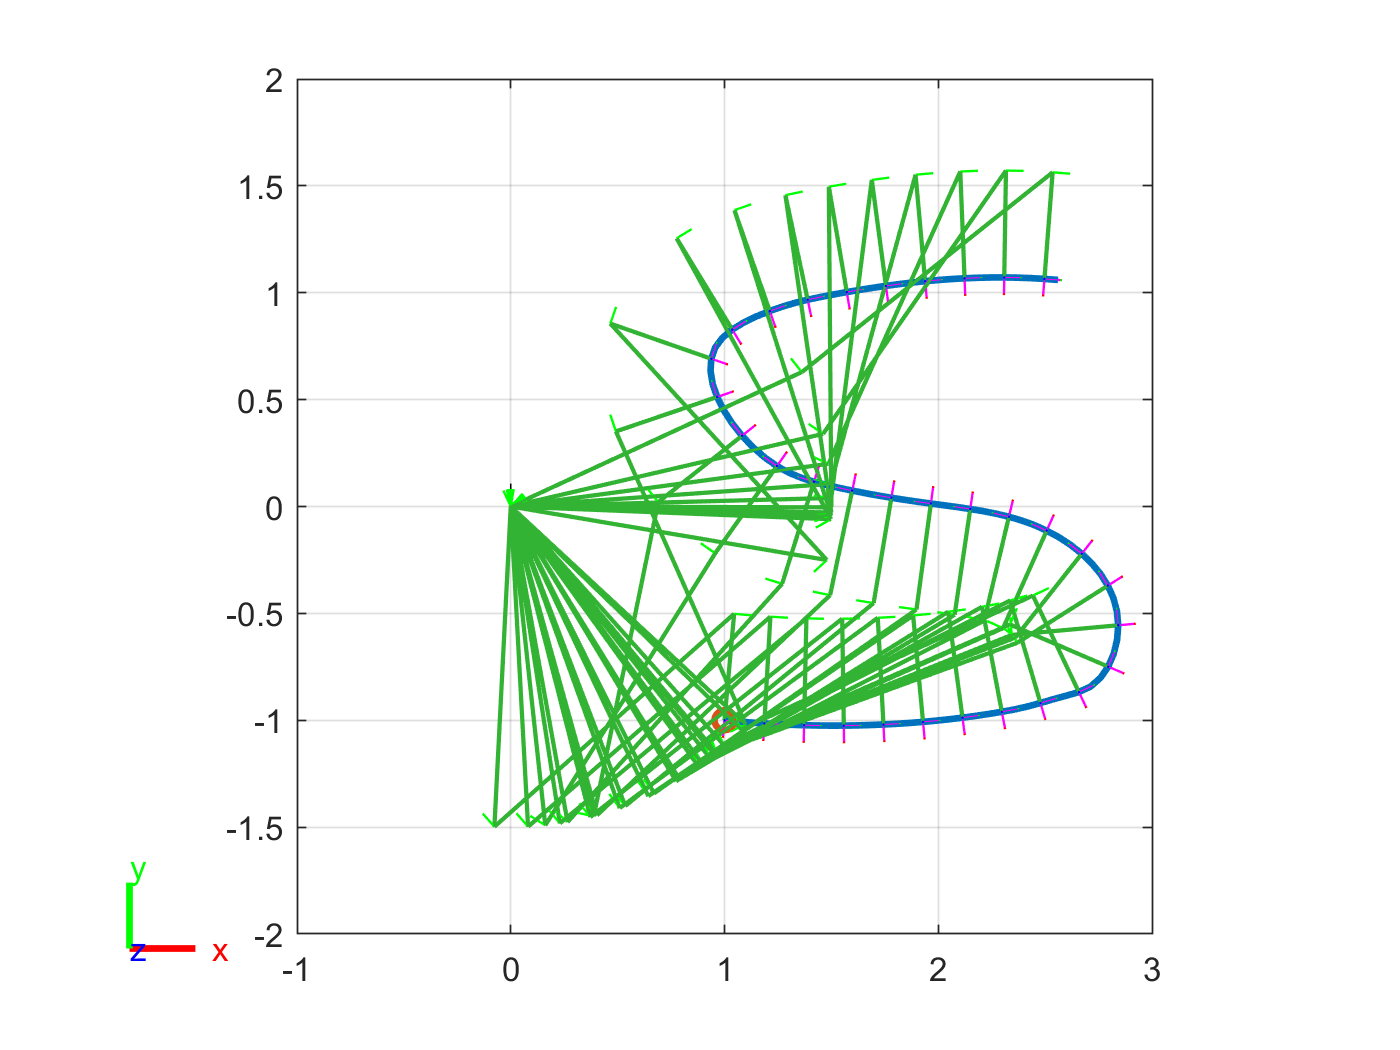

figure(5);plot(Sls(1,:),Sls(2,:),Sls(1,1),Sls(2,1),'o','linewidth',2);
hold on
grid on; axis([-1,3,-2,2]);axis('square');
for i=1:3:nl-1 % plot every some of them to make a cleaner plot
    robot.q=qsol1(:,i);pause(.1);
    show(robot_rb,robot.q,'Collision','on'); 
    view(0,90);
end

fprintf('max joint speed: %5.4f, %5.4f, %5.4f\n',max(abs(diff(qsol1')')')');

max joint speed: 0.2348, 0.3705, 0.4292


Plot solution 2s

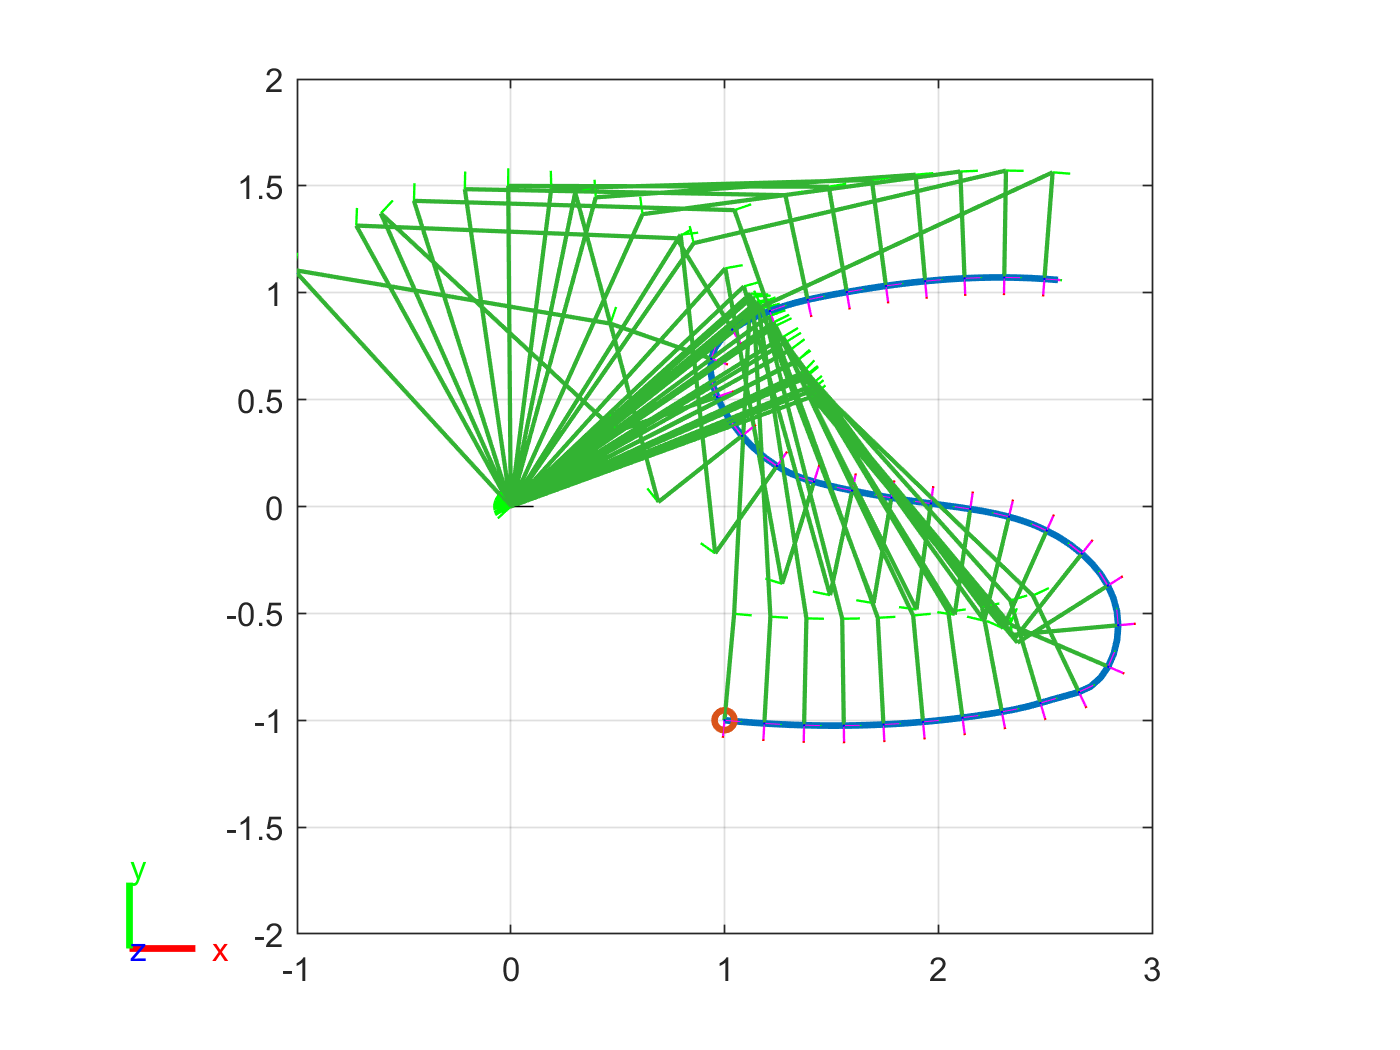

figure(6);plot(Sls(1,:),Sls(2,:),Sls(1,1),Sls(2,1),'o','linewidth',2);
hold on
axis([-1,3,-2,2]);axis('square');
for i=1:3:nl-1 % plot every some of them to make a cleaner plot
    robot.q=qsol2(:,i);pause(.1);
    show(robot_rb,robot.q,'Collision','on'); 
    view(0,90);
end
grid on;

fprintf('max joint speed: %5.4f, %5.4f, %5.4f\n',max(abs(diff(qsol2')')')');

max joint speed: 0.2237, 0.3705, 0.4232


% dqdt = 0.4292; % rad/sec
% dqdlmax1 = max(abs(diff(qsol1')./diff(lambda(1:end)'))');
% dldt1 = dqdt./dqdlmax1;
% dqdlmax2 = max(abs(diff(qsol2')./diff(lambda(1:end)'))');
% dldt2 = dqdt./dqdlmax2;
% 
% dldtmin1 = min(dldt1);
% dldtmin2 = min(dldt2);
% 
% figure;plot(lambda(1:end-1),dldt1,'linewidth',2);
% hold on;plot(lambda(1:end-1),dldt2,'linewidth',3,'LineStyle',"--");
% hold off
% legend(['elbow-up v_{min}= ',num2str(round(dldtmin1,2))],...
% ['elbow-down v_{min}= ',num2str(round(dldtmin2,2))])
% xlabel('\lambda (m)')
% ylabel('d\lambda/dt (m/s)')
% xlim([0,lambda(end-1)])
% title('Max End-effector Speed Along the Path')

## FUNCTIONS

### Calculate a path's (S) normal and parallel unit vectors (xT and yT respectively) at each point

function [xT,yT]=setR0T(S)
    ez=[0;0;1];
    yT=[diff(S')'./vecnorm(diff(S')');zeros(1,length(S)-1)];
    xT=-crossmat(ez)*yT;
end

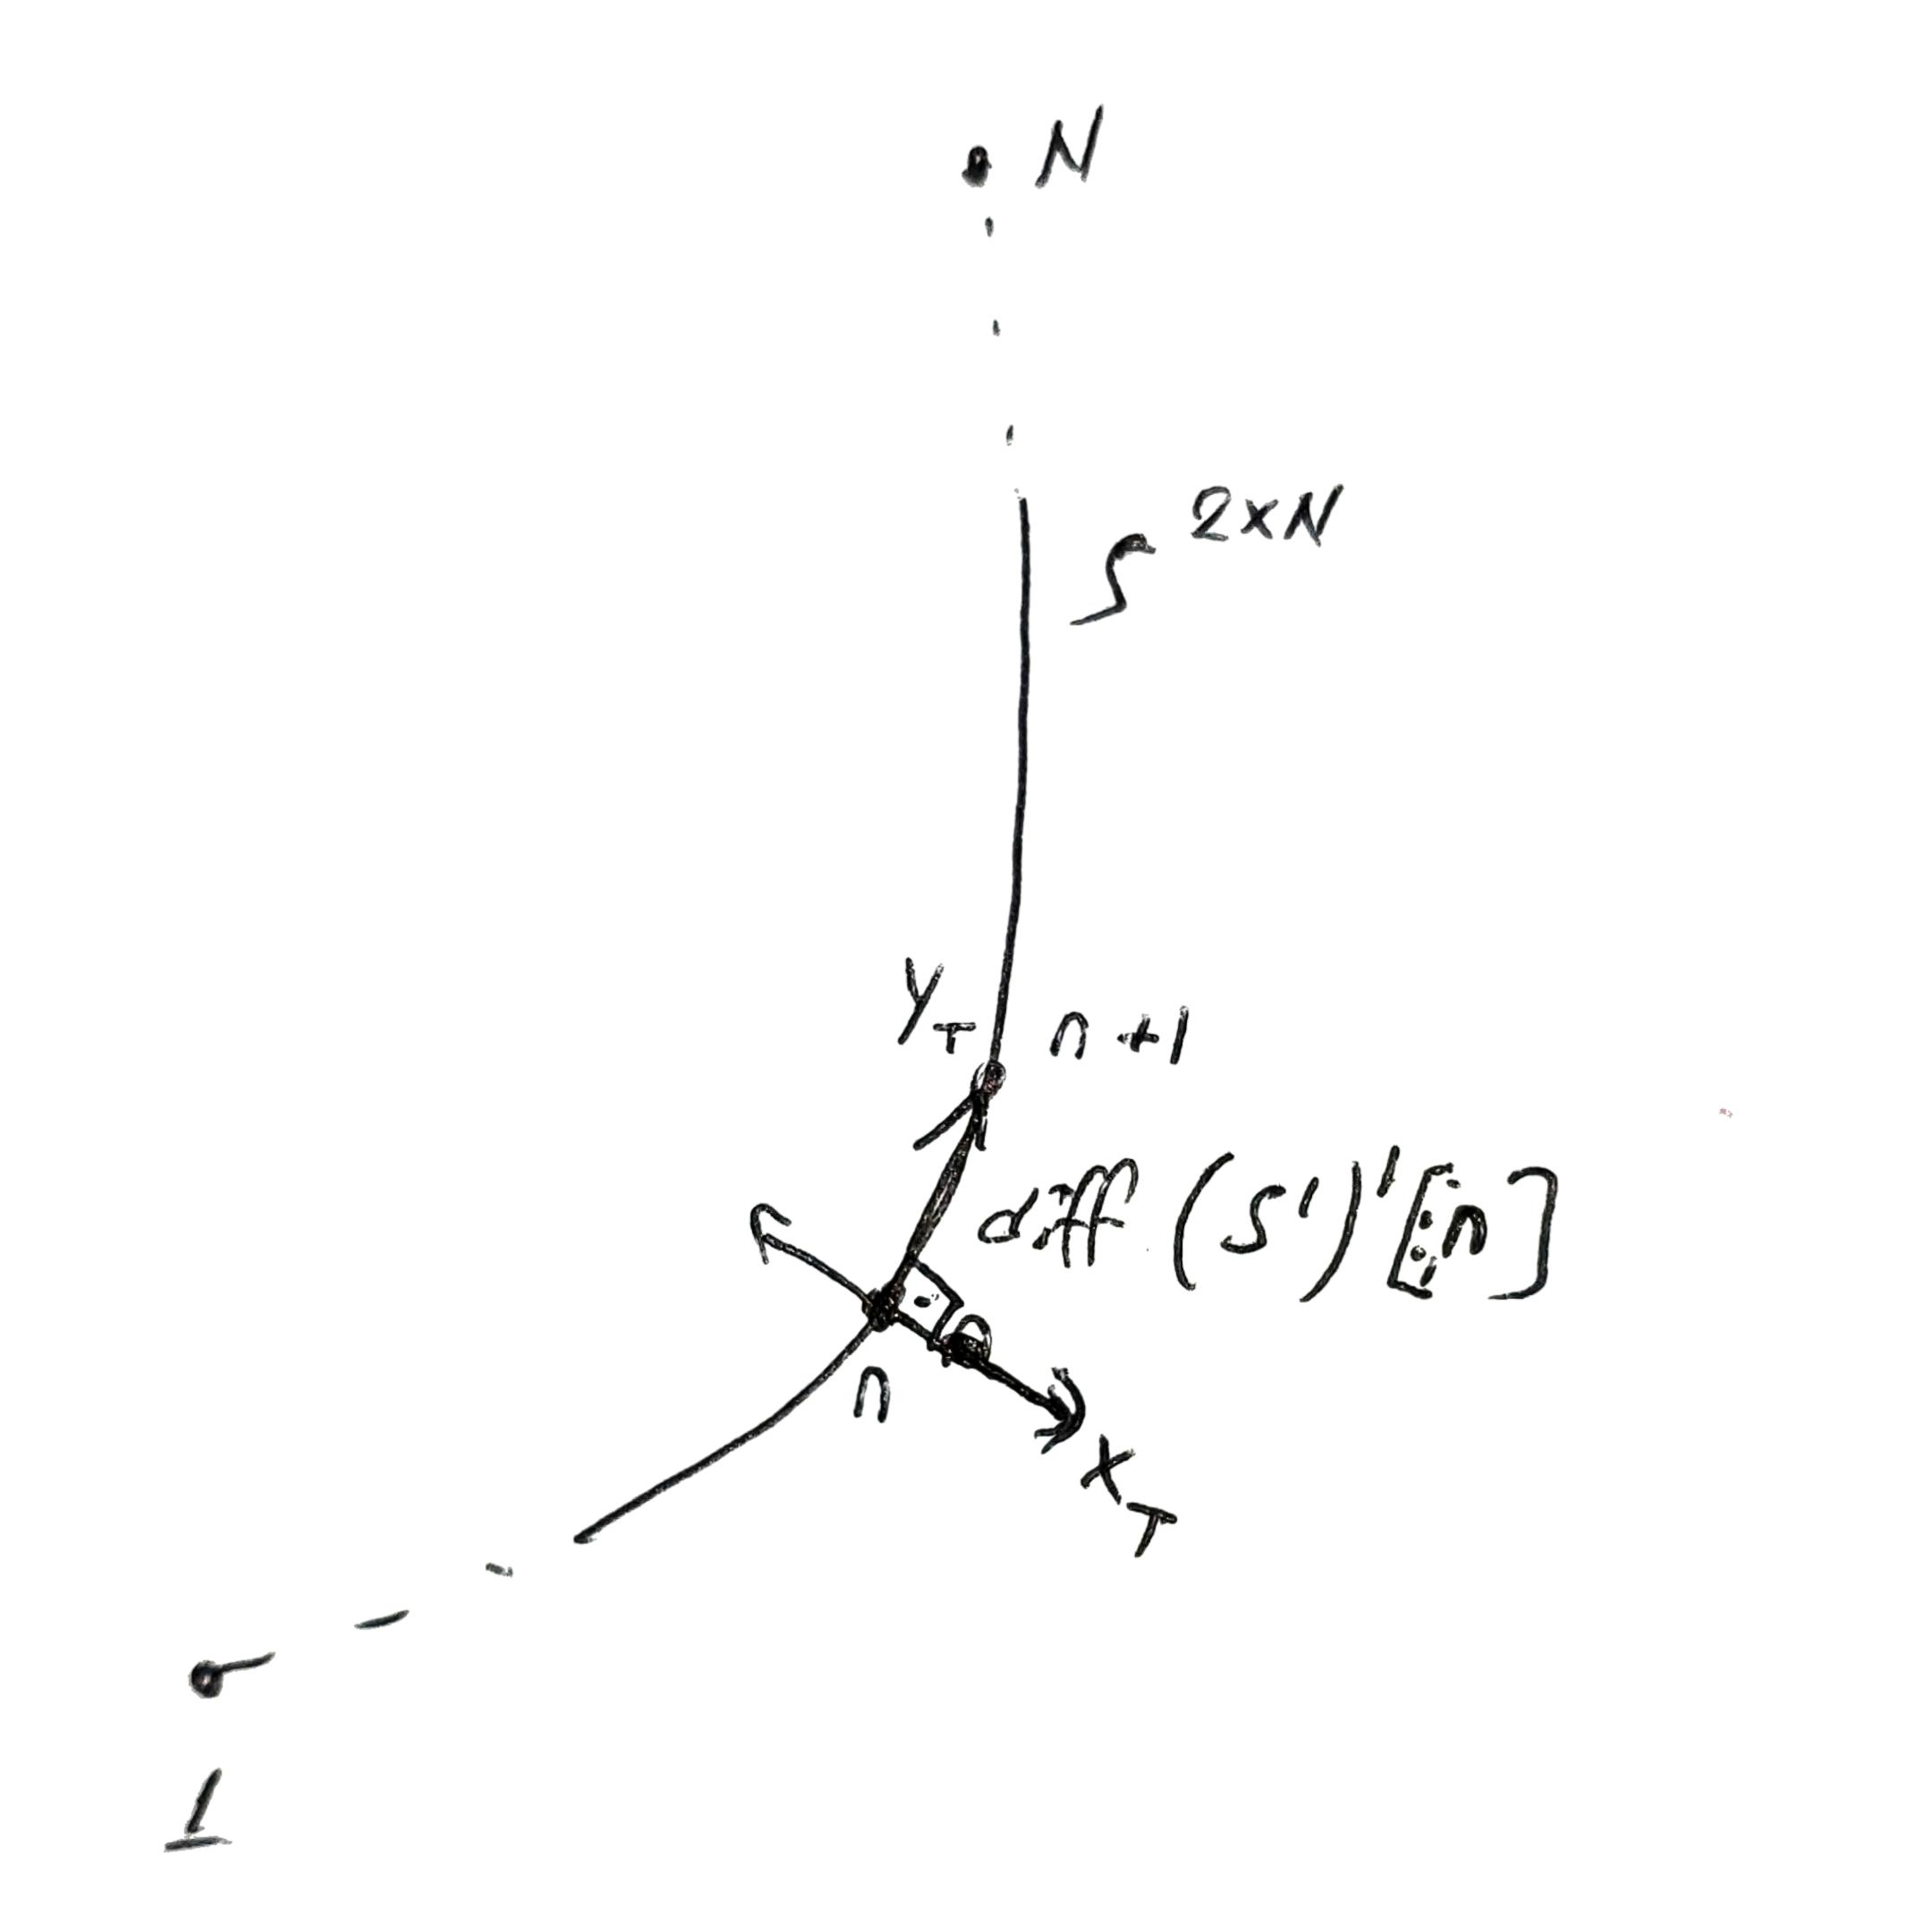

### For cross multiplication

function vhat=crossmat(v)
    % 3x3 skew-symmetric matrix
    vhat = [0 -v(3) v(2);v(3) 0 -v(1);-v(2) v(1) 0];
end

### Calculate Forward Kinematics Pose and Jacobian

%
% forward kinematics of an n-link all revolute joint planar arm 
%
% input:    robot = robot object with
%                   .q = (n x 1) joint displacement
%                   .H = [h1, ..., hn] (3xn)
%                   .P = [p01, ..., p_{n-1,n},p_{n,T}] (3x(n+1))
%                   .joint_type = 1xn (0 for revolute, 1 for prismatic)
% 
% output:   robot = robot object with the following attributes filled in
%                   .T = homogenous transform T_{0T}
%                   .J = Jacobian J_T in 0 frame
%
% usage:
%       robot=nlinkfwdkin(robot)
%

function robot = nlinkfwdkin(robot)

    % Extract # of links
    n=length(robot.q);
    
    % ********** calculate T_{0T} ***********
    % orientation of end effector
    qT=sum(robot.q);
    % for position, start with the first link p01 (stationary)
    p0T=robot.P(1:2,1);
    % calculate R_{0i} p_{i,i+1}, i=1,..,n
    for i=1:n
        P(:,i)=rot2(sum(robot.q(1:i)))*robot.P(1:2,i+1);
    end
    % p0T = sum_{i=0}^n R_{0i} p_{i,i+1},
    p0T=p0T+sum(P,2);
    
    % output the homogeneous matrix
    %robot.T=eye(4,4);
    robot.T(1:2,4)=p0T;
    robot.T(1:2,1:2)=rot2(qT);
    robot.T(3,3)=1;
    robot.T(4,4)=1;
    
    %
    % ********** calculate J_T ***********
    % 
    % set up cross product 
    ez_cross=[0 -1;1 0];
    % ith column of J is [1;ez x \sum_{k=i}^n R_{0k} p_{k,k+1}]
    for i=1:n
        robot.J(2:3,i)=ez_cross*sum(P(:,i:n),2);
        robot.J(1,i)=1;
    end

end


### Geometric inverse kinematics for 3-link planar arm

%
% inverse kinematics of a 3-link all revolute joint planar arm 
%
% input:    robot = robot object with
%                   .T = homogenous transform T_{0T}
%                   .H = [h1, ..., hn] (3xn)
%                   .P = [p01, ..., p_{n-1,n},p_{n,T}] (3x(n+1))
%                   .joint_type = 1xn (0 for revolute, 1 for prismatic)
% 
% output:   q = all solutions of [q1;q2;q3] in columns
%

function q=threelink_invkin_geometric(robot)

    ez=[0;0;1];
    qT=atan2(robot.T(2,1),robot.T(1,1));
    p0T=robot.T(1:3,4);
    
    p13=p0T-robot.P(:,1)-robot.T(1:3,1:3)*robot.P(:,4);
    
    % use law of cosine
    a=norm(robot.P(:,2));
    b=norm(robot.P(:,3));
    c=norm(p13);
    q2=zeros(2,1);
    q2(1)=pi-acos((a^2+b^2-c^2)/(2*a*b));
    q2(2)=pi+acos((a^2+b^2-c^2)/(2*a*b));
    %q2=subprob3(ez,-robot.P(:,3),robot.P(:,2),norm(p13));
    %restrict to be within [-pi,pi]
    q2=(q2>pi).*(-2*pi+q2)+(q2<-pi).*(2*pi+q2)+(q2<pi).*(q2>-pi).*q2;
    
    q=zeros(3,length(q2));
    for i=1:length(q2)
        p13_1=robot.P(1:2,2)+rot2(q2(i))*robot.P(1:2,3);
        q(1,i)=2*atan2(norm(p13_1-p13(1:2)),norm(p13_1+p13(1:2)));
        q(1,i)=sign(cross([p13_1;0],p13)'*ez)*q(1,i);
        q(2,i)=q2(i);
        q(3,i)=qT-q(2,i)-q(1,i);
    end
    q(3,:)=(q(3,:)>pi).*(-2*pi+q(3,:))+(q(3,:)<-pi).*(2*pi+q(3,:))+...
        (q(3,:)<pi).*(q(3,:)>-pi).*q(3,:);

end

### Geometric inverse kinematics for 3-link planar arm - with subproblems

Note that the subproblem functions are already given in the MATLAB Utility code folder in the previous assignment.

%
% inverse kinematics of a 3-link all revolute joint planar arm 
%
% input:    robot = robot object with
%                   .T = homogenous transform T_{0T}
%                   .H = [h1, ..., hn] (3xn)
%                   .P = [p01, ..., p_{n-1,n},p_{n,T}] (3x(n+1))
%                   .joint_type = 1xn (0 for revolute, 1 for prismatic)
% 
% output:   q = all solutions of [q1;q2;q3] in columns
%

function q=threelink_invkin_geometric2(robot)

    ez=[0;0;1];
    qT=atan2(robot.T(2,1),robot.T(1,1));
    p0T=robot.T(1:3,4);
    
    p13=p0T-robot.P(:,1)-robot.T(1:3,1:3)*robot.P(:,4);
    q2=subprob3(ez,-robot.P(:,3),robot.P(:,2),norm(p13));
    %restrict to be within [-pi,pi]
    q2=(q2>pi).*(-2*pi+q2)+(q2<-pi).*(2*pi+q2)+(q2<pi).*(q2>-pi).*q2;
    
    q=zeros(3,length(q2));
    for i=1:length(q2)
        q(1,i)=subprob0([0;0;1],...
            robot.P(:,2)+rot(robot.H(:,2),q2(i))*robot.P(:,3),...
            p13);
        q(2,i)=q2(i);
        q(3,i)=qT-q(2,i)-q(1,i);
    end
    q(3,:)=(q(3,:)>pi).*(-2*pi+q(3,:))+(q(3,:)<-pi).*(2*pi+q(3,:))+...
        (q(3,:)<pi).*(q(3,:)>-pi).*q(3,:);

end

### 2D rotation matrix with given rotation angle (ie 2x2 portion of rotation around z axis)

function R=rot2(q)
    c=cos(q);s=sin(q);
    R=[c -s;s c];
end